clear all

global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;

h = 0.1;
z0 = [2.1837 0.0];
dtlin = zeros(size(1:6));
dxlin = zeros(size(1:6));
for i = 1:6
    h
    dtlin(i) = h;
    dxlin(i) = abs(z0(1)-RK4quad(z0, h));
    h = h/10;
end

h = 0.1000

h = 0.0100

h = 1.0000e-03

h = 1.0000e-04

h = 1.0000e-05

h = 1.0000e-06

save("cycle_quad.mat")

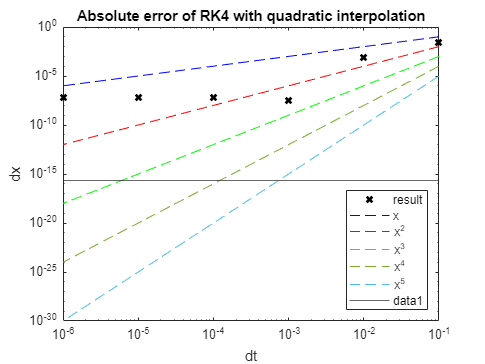

load("cycle_quad.mat")
loglog(dtlin,dxlin,"xblack",'LineWidth',2)
hold on
loglog(dtlin,dtlin,"b--")
loglog(dtlin,dtlin.^2,"r--")
loglog(dtlin,dtlin.^3,"g--")
loglog(dtlin,dtlin.^4,"--")
loglog(dtlin,dtlin.^5,"--")
hold off
xlabel("dt"), ylabel("dx")
legend("result","x","x^2","x^3","x^4","x^5",'Location',"southeast")
title("Absolute error of RK4 with quadratic interpolation")
yline(2^-52)

function dz=odefcn(z)
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1) ,z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function xzero = RK4quad(z0, h)
    xm1 = z0(1);
    ym1 = z0(2);
    
    k1 = odefcn([xm1, ym1]);
    k2 = odefcn([xm1 + k1(1) * h/2, ym1 + k1(2) * h/2]);
    k3 = odefcn([xm1 + k2(1) * h/2, ym1 + k2(2) * h/2]);
    k4 = odefcn([xm1 + k3(1) * h  , ym1 + k3(2) * h  ]);
    
    x = xm1 + (h/6) * (k1(1) + 2*k2(1) + 2*k3(1) + k4(1));
    y = ym1 + (h/6) * (k1(2) + 2*k2(2) + 2*k3(2) + k4(2));
    
    count = 0;
    
    while count < 2
        xm2 = xm1;
        ym2 = ym1;
        xm1 = x;
        ym1 = y;
        
        k1 = odefcn([xm1, ym1]);
        k2 = odefcn([xm1 + k1(1) * h/2, ym1 + k1(2) * h/2]);
        k3 = odefcn([xm1 + k2(1) * h/2, ym1 + k2(2) * h/2]);
        k4 = odefcn([xm1 + k3(1) * h  , ym1 + k3(2) * h  ]);
    
        x = xm1 + (h/6) * (k1(1) + 2*k2(1) + 2*k3(1) + k4(1));
        y = ym1 + (h/6) * (k1(2) + 2*k2(2) + 2*k3(2) + k4(2));
        
        if y*ym1 < 0
            count = count+1;
        end
        
    end
    
    xzero = xm2 * (ym1 * y  )   / ((ym2 - ym1) * (ym2 - y  )) + ...
            xm1 * (ym2 * y  )   / ((ym1 - ym2) * (ym1 - y  )) + ...
            x   * (ym2 * ym1)   / ((y   - ym2) * (y   - ym1));
    
end